clear all
close all
clc

**README: **

- This pipeline is for extracting parameters of the STAIRS test. 

- For running the pipeline you require all functions and Xsens excel files. Change the location of the selected feature accordingly, if needed.

- **IMPORTANT. You will need to watch the task on the Xsens MVN reader to determine if the person is doing alternating or non-alternating stair climbing. If the person is climbing alternating, only extract the alternating climbs and avoid including single stair climbs at the beginning or end of the task. Make sure to label the person in the item tracking excel file as "Alternating" or "Non-Alternating". **

# **Manual Gait Segmentation**

**In this part, you can do gait segmentation for the stairs task. There will be four plots asking you to mark joint angle peaks of left and right side during stair ascending and descending. Make sure to:**

- Look at the reference plot and find out the period of climbing and do not considering the overground walking time

- Participants may have alternative or non-alternative climbing. Make sure to consider this fact in selecting steps. 

- Participants were instructed to turn at the top and climb down. I used the trunk orientation signal as a reference to know the turning onset, sometimes they attempt to turn during the last step. Make sure to include or exclude that step in the peak selection. 

**The output of this part is a segmented structure saved for four type of steps. Climbing up on right side, climbing up on left side, climbing down on right side, climbing down on left side. **

%load the Extracted File
base_path = 'Y:\P2C\P2C_Database_Segmented - Database paper version\Control';
subject = 'HC01';
activity = 'STAIRS_1_1';
file_name = [subject '_' activity '_Extracted.mat'];

file_path = fullfile(base_path, subject, activity, 'Sensor Data', 'Xsens', file_name);

data = load(file_path)

%load the parameter tables
load('Y:\LabMembers\S Daneshgar\P2C\Codes\Stair\ParametersSTAIRS.mat');

[ascendingLeft, descendingLeft, ascendingRight, descendingRight] = plotmarker(data);
processedData = segmentation(data, ascendingLeft, ascendingRight, descendingLeft, descendingRight);


data = struct with fields:
    xsens_ord: [1×1 struct]


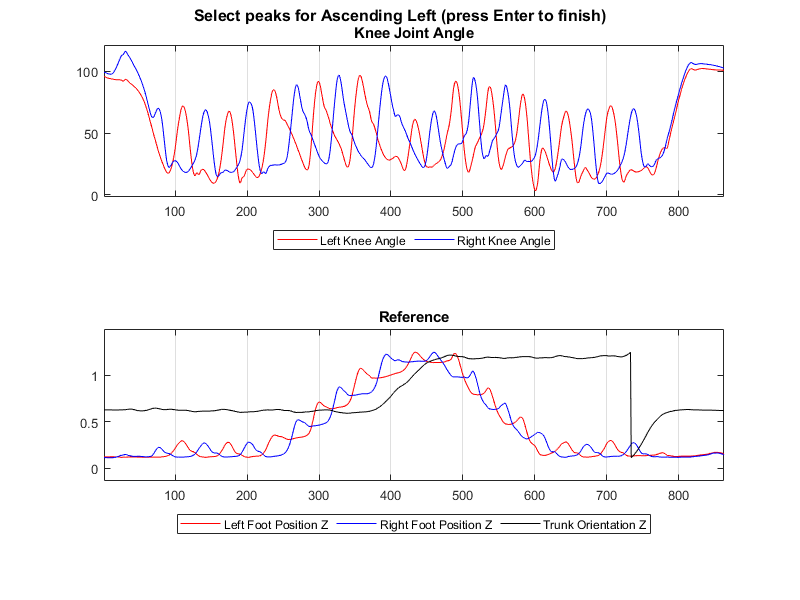

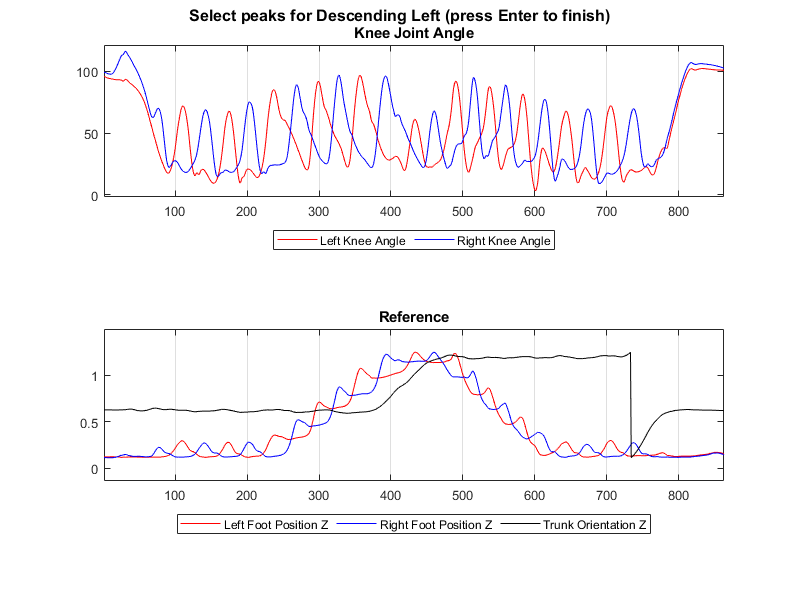

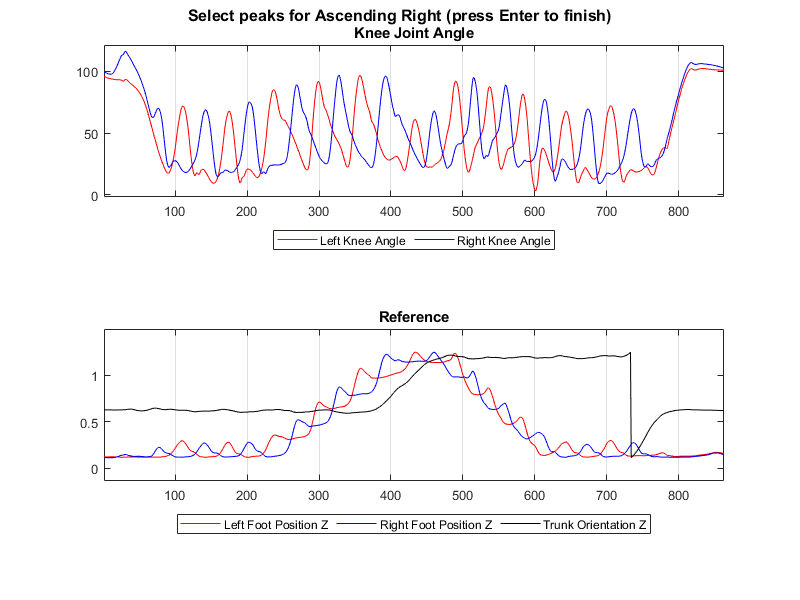

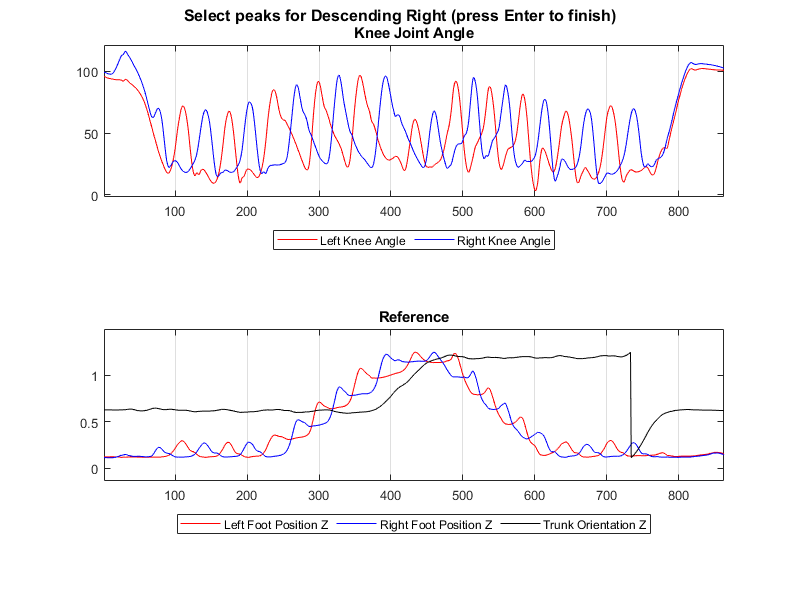

%Export table with stairs as rows and parameters as columns
ExportparametersSTAIRS = array2table(nan(max(max(max(size(processedData.AscendingLeft.Pos, 1), size(processedData.AscendingRight.Pos, 1)), size(processedData.DescendingLeft.Pos, 1)), size(processedData.DescendingRight.Pos, 1)), numel(names)), 'VariableNames', names);
%Assigned body sides and phase of climbing in the structure
bodyside = {'AscendingLeft', 'AscendingRight', 'DescendingLeft', 'DescendingRight'};

`Alternating climbing = 1, Non-alternating climbing = 0`

Alternate = 1; 
subject_code = 'HC01'

# **Calculating Cadence (step/min) and Step Time (s)**

This code basically measures the duration of each step (Instantenous cadence) and connects to number of multiple steps per minute. 

Note: For sure we always need an inspection!

%Calculating Cadence (step/min) and Step time (s) and their Assym (%)
ExportparametersSTAIRS = Cadence(processedData, bodyside, Alternate, ExportparametersSTAIRS);

# **Calculating Step Length (m)**

%Calculating step length (m) and step length assymetry (%)
ExportparametersSTAIRS = StepLength(processedData, bodyside, ExportparametersSTAIRS);

# **Calculating Midswing Elevation (m) and Circumduction (m)**

%Calculating midswing elevation (m) and circumduction (m) and their assymetries (%)
ExportparametersSTAIRS = Elevation(processedData, bodyside, ExportparametersSTAIRS);

# **Calculating Knee Flexion and Hip Abduction (ROM Degrees)**

%Calculating maximum Knee Flexion and Hip Abduction (Degrees)

subject_code = 'HC01_segmented'

%Calculating Asymmetries (%)
ExportparametersSTAIRS = FlexionAbduction(processedData, bodyside, ExportparametersSTAIRS);

# **Calculating Trunk ROM (X, Y, Z; degrees)**

%Calculating Trunk ROM
ExportparametersSTAIRS = TrunkROM(processedData, ExportparametersSTAIRS);

# **Saving the Gait Parameters**

% Transpose the data and create a table with dynamic column names
transposedData = ExportparametersSTAIRS.Variables';
numColumns = size(transposedData, 2);
dynamicColumnNames = strcat('Stride', string(1:numColumns));
newExportparameters = array2table(transposedData, 'VariableNames', dynamicColumnNames);
newExportparameters = addvars(newExportparameters, names', 'Before', 1, 'NewVariableNames', 'Parameter');

% Define dynamic filenames for Excel and segmented files
dynamic_filename_excel = sprintf('%s_%s_Parameters.csv', subject, activity); % e.g., HC01_STAIRS_1_1_parameters.csv
dynamic_filename_segmented = sprintf('%s_%s_Segmented.mat', subject, activity); % e.g., HC01_STAIRS_1_1_segmented.mat

% Construct the file paths
file_path_excel = fullfile(base_path, subject, activity, 'Sensor Data', 'Xsens', dynamic_filename_excel);
file_path_segmented = fullfile(base_path, subject, activity, 'Sensor Data', 'Xsens', dynamic_filename_segmented);

% Write the table to the specified Excel file path
writetable(newExportparameters, file_path_excel); % Save as HC01_STAIRS_1_1_parameters.csv

% Save the processed data to the segmented MAT file
save(file_path_segmented, 'processedData'); % Save as HC01_STAIRS_1_1_segmented.mat
